# Demonstration of Filter, Normalization and Batch Correction of Data in scGEApp

## Read scRNA-seq data, X and Y

[X,genelistx]=sc_readfile('example_data/GSM3204304_P_P_Expr_999cells.csv');

Reading example_data/GSM3204304_P_P_Expr_999cells.csv ...... done.


[Y,genelisty]=sc_readfile('example_data/GSM3204305_P_N_Expr_999cells.csv');

Reading example_data/GSM3204305_P_N_Expr_999cells.csv ...... done.


## Select genes with at least 3 cells having more than 5 reads per cell.

[X,genelistx]=sc_selectg(X,genelistx,5,3);
[Y,genelisty]=sc_selectg(Y,genelisty,5,3);

## Obtain gene intersection of X and Y

[genelist,i,j]=intersect(genelistx,genelisty,'stable');
X=X(i,:);
Y=Y(j,:);
% libsizex=sum(X);
% libsizey=sum(Y);
% X=X(:,libsizex>quantile(libsizex,0.3)&libsizex<quantile(libsizex,0.95));
% Y=Y(:,libsizey>quantile(libsizey,0.3)&libsizey<quantile(libsizey,0.95));
clearvars -except X Y genelist

## Show raw data

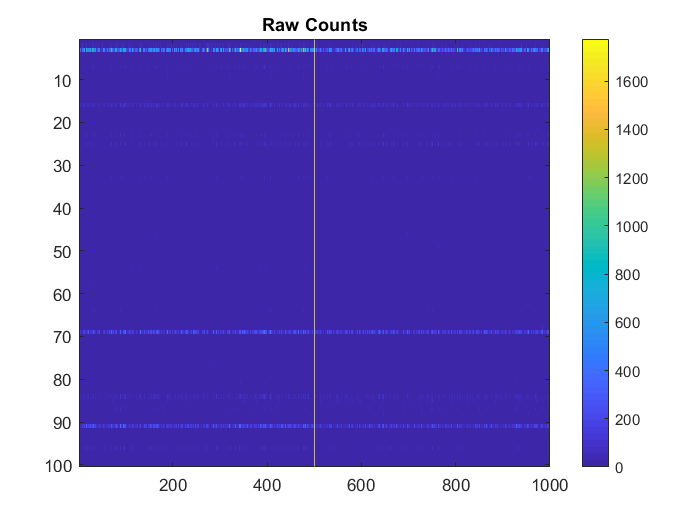

figure; imagesc([X(1:100,1:500) Y(1:100,1:500)]); title('Raw Counts'); colorbar; xline(500,'y-');

## Show DESeq normalized data

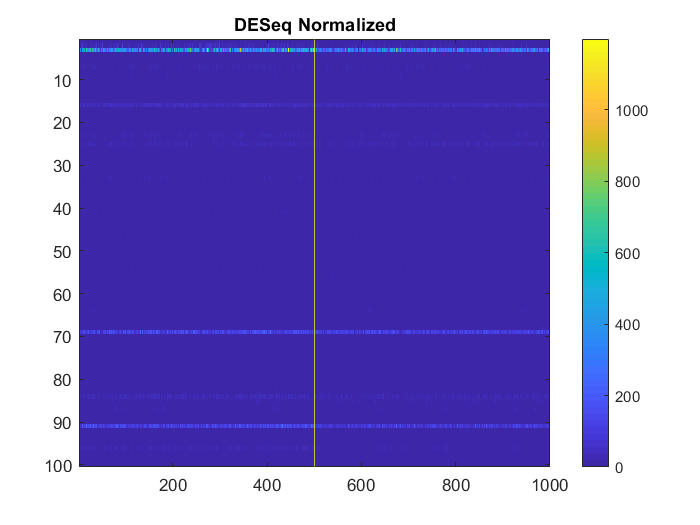

[Xs]=sc_norm(X,'type','deseq');
[Ys]=sc_norm(Y,'type','deseq');
figure; imagesc([Xs(1:100,1:500) Ys(1:100,1:500)]); title('DESeq Normalized'); colorbar; xline(500,'y-');

## Show library-size normalized data

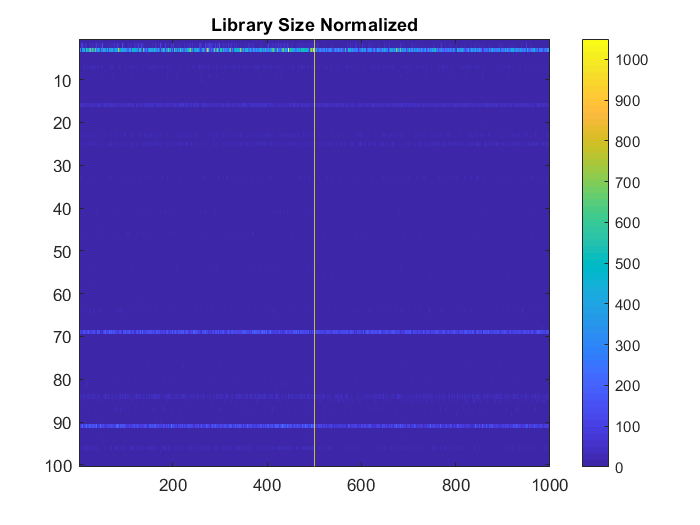

[X]=sc_norm(X,'type','libsize');
[Y]=sc_norm(Y,'type','libsize');
figure; imagesc([X(1:100,1:500) Y(1:100,1:500)]); title('Library Size Normalized'); colorbar; xline(500,'y-');

## Log(x+1) transformed normalized data

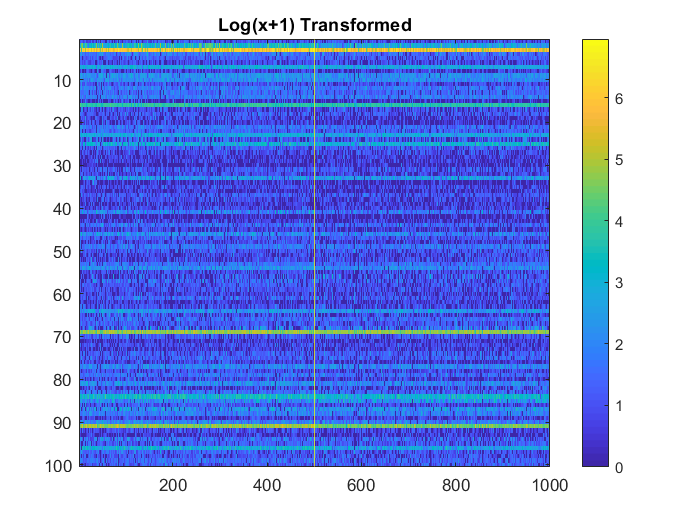

X=log(X+1);
Y=log(Y+1);
figure; imagesc([X(1:100,1:500) Y(1:100,1:500)]); title('Log(x+1) Transformed'); colorbar; xline(500,'y-');

## Show HCP normalized data

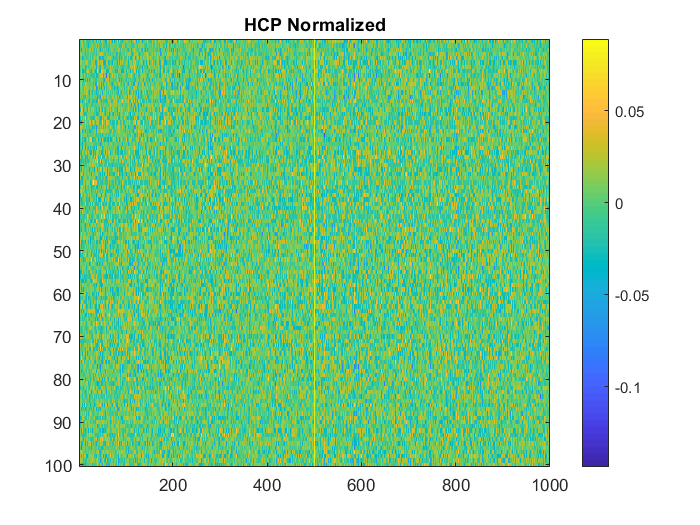

[Xm,Ym]=run_hcp(X,Y);
figure; imagesc([Xm(1:100,1:500) Ym(1:100,1:500)]); title('HCP Normalized'); colorbar; xline(500,'y-');

## Show data with ComBat batch correction

[Xn,Yn]=run_combat(X,Y);

[combat] Found 2 batches
[combat] Adjusting for 0 covariate(s) of covariate level(s)
[combat] Standardizing Data across features
[combat] Fitting L/S model and finding priors
[combat] Finding parametric adjustments
[combat] Adjusting the Data


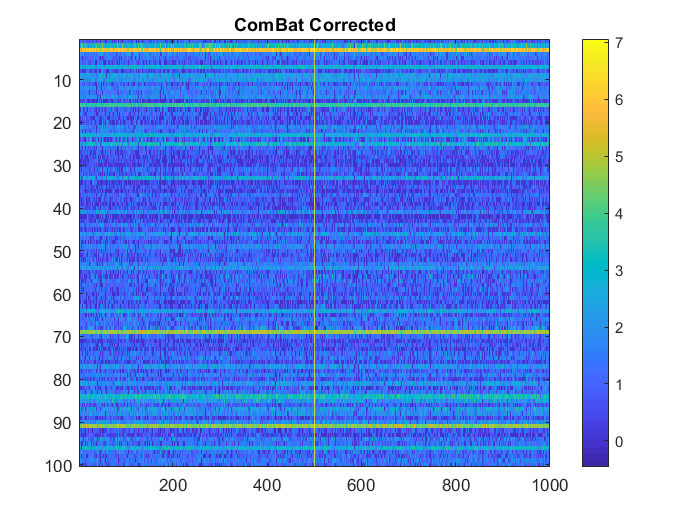

figure; imagesc([Xn(1:100,1:500) Yn(1:100,1:500)]); title('ComBat Corrected'); colorbar; xline(500,'y-');

## Show data subject to MAGIC imputation

Xo=run_magic(X);

doing PCA
computing kernel
Computing alpha decay kernel:
Number of samples = 999
First iteration: k = 300
Number of samples below the threshold from 1st iter: 932
Using radius based search for the rest
   Symmetrize affinities
   Done computing kernel
imputing using optimal t
t = 1
t = 2
t = 3
t = 4
t = 5
t = 6
t = 7
t = 8
t = 9
optimal t = 9
done.


Yo=run_magic(Y);

doing PCA
computing kernel
Computing alpha decay kernel:
Number of samples = 999
First iteration: k = 300
Number of samples below the threshold from 1st iter: 898
Next iteration: k= 999
Number of samples below the threshold from the next iter: 999
   Symmetrize affinities
   Done computing kernel
imputing using optimal t
t = 1
t = 2
t = 3
t = 4
t = 5
t = 6
t = 7
t = 8
t = 9
optimal t = 9
done.


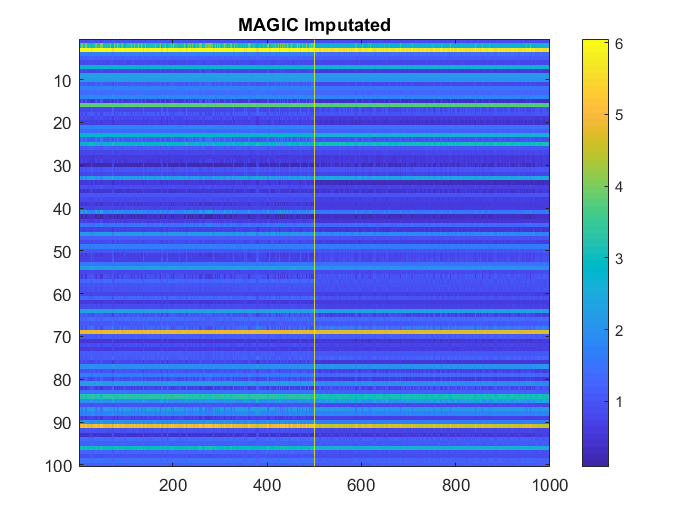

figure; imagesc([Xo(1:100,1:500) Yo(1:100,1:500)]); title('MAGIC Imputated'); colorbar; xline(500,'y-');

## The End